# Report for IMU test

clc
clear
load("C:\Users\mgloria\Desktop\iit\icub-tests\test_imu_2024_04_02_11_33_34.mat");

## Robot name

IMU test ran on:

robotName = test_imu.yarp_robot_name;
fprintf(robotName)

iCubGazeboV2_7

## Euler angles

The IMU test aims to check the consistency of the Euler angles values streamed by the IMU mounted on the FTs compared to the measures obtained with the Forward Kinematics. 

In this section, for each analyzed sensor, plots comparing the expected and measured values are provided, divided into roll, pitch, and yaw components.

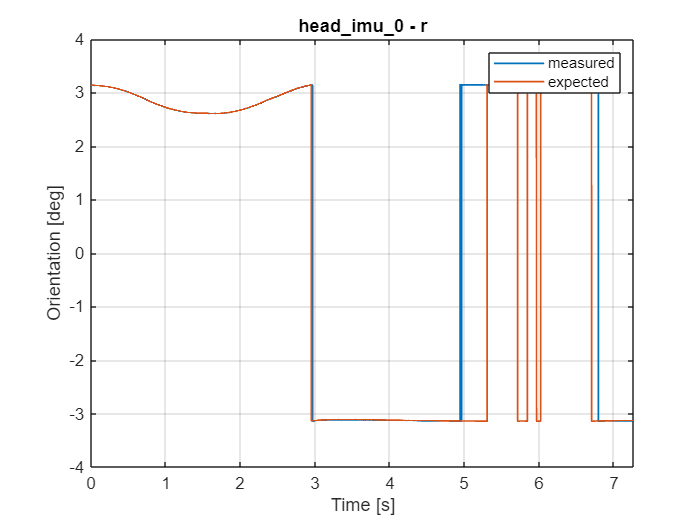

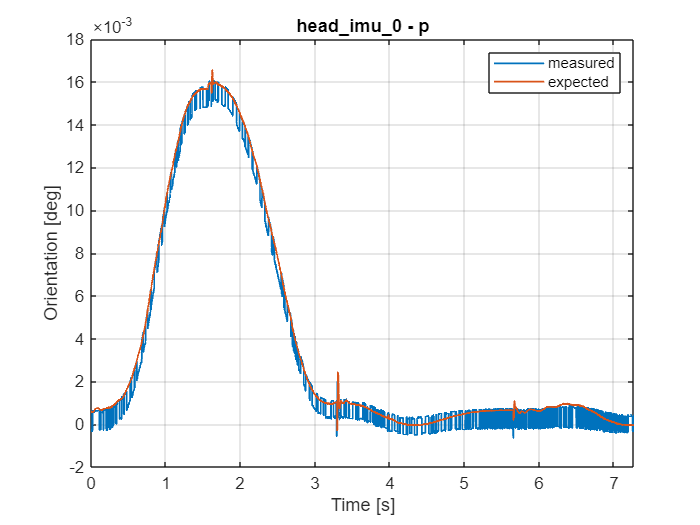

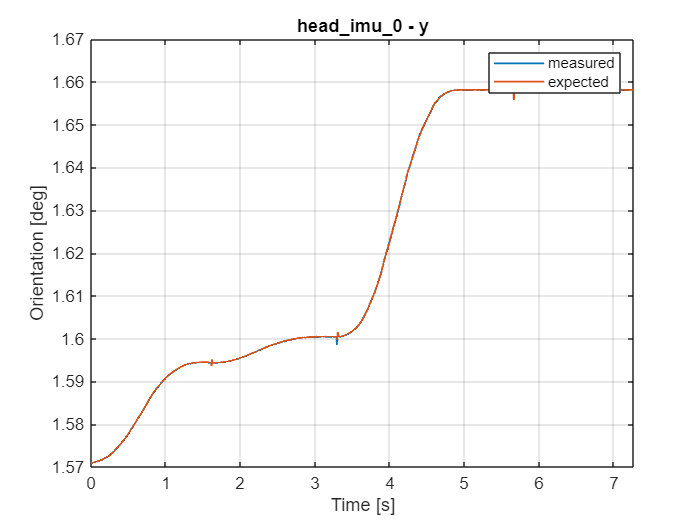

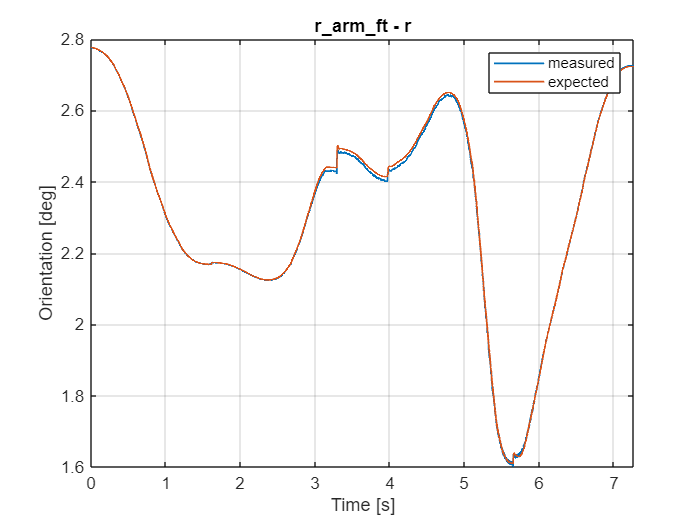

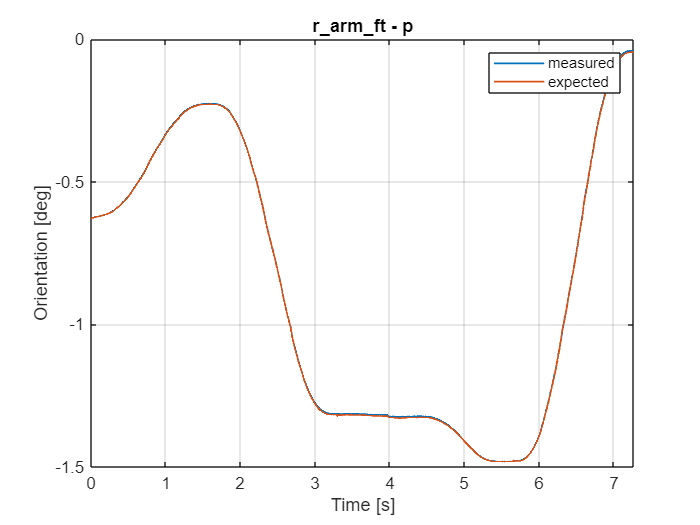

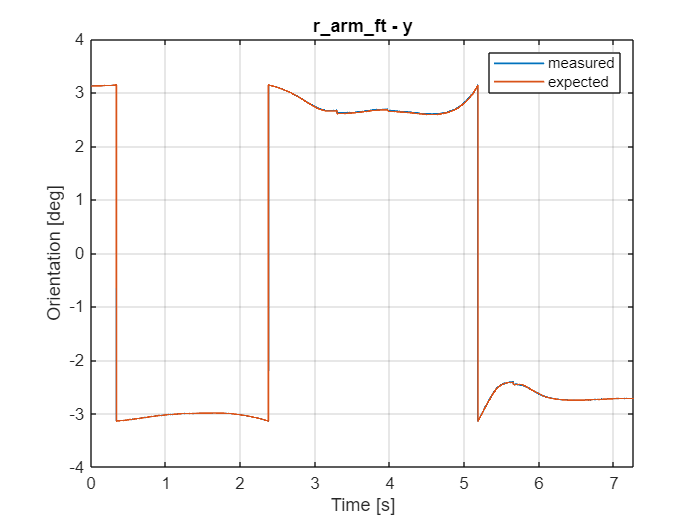

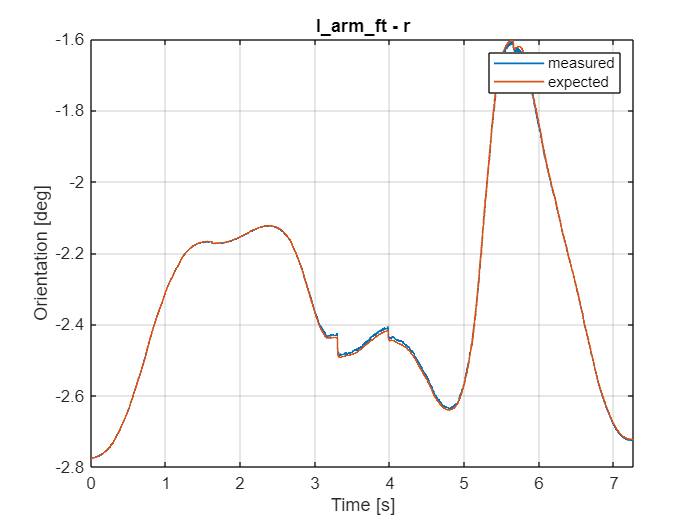

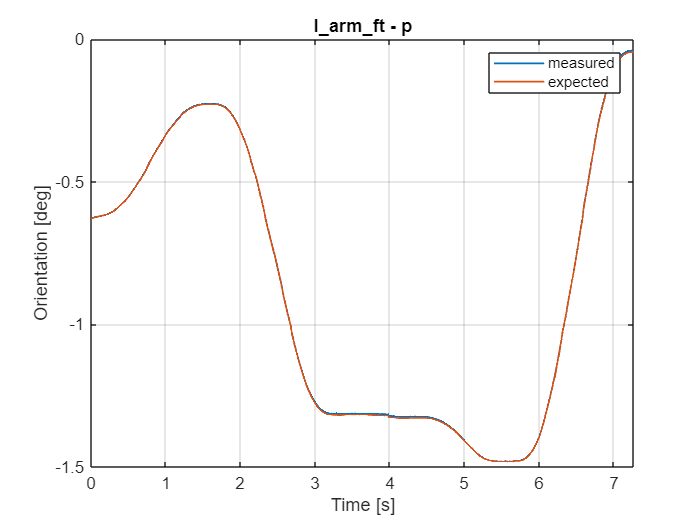

orientations = test_imu.orientations;
sensorName = fieldnames(orientations);
time = test_imu.joints_state.positions.timestamps;
time = time - time(1,1);

for i = 1:numel(fieldnames(orientations))
    measured = orientations.(string(sensorName(i))).measured.data;
    expected = orientations.(string(sensorName(i))).expected.data;
    error(i,:,:) = rad2deg(orientations.(string(sensorName(i))).error.data);
    figure
    plot(time(1:length(expected)), expected(1,:), LineWidth=1);
    grid on
    hold on
    plot(time(1:length(measured)), measured(1,:), LineWidth=1);
    xlim([0, time(length(expected))])
    xlabel("Time [s]")
    ylabel("Orientation [deg]")
    title(string(sensorName(i)) + " - " + orientations.(string(sensorName(i))).expected.elements_names(1), 'Interpreter','none');
    legend("measured", "expected")

    figure
    plot(time(1:length(expected)), expected(2,:), LineWidth=1);
    grid on
    hold on
    plot(time(1:length(measured)), measured(2,:), LineWidth=1);
    xlim([0, time(length(expected))])
    xlabel("Time [s]")
    ylabel("Orientation [deg]")
    title(string(sensorName(i)) + " - " + orientations.(string(sensorName(i))).expected.elements_names(2), 'Interpreter','none');
    legend("measured", "expected")

    figure
    plot(time(1:length(expected)), expected(3,:), LineWidth=1);
    grid on
    hold on
    plot(time(1:length(measured)), measured(3,:), LineWidth=1);
    xlim([0, time(length(expected))])
    xlabel("Time [s]")
    ylabel("Orientation [deg]")
    title(string(sensorName(i)) + " - " + orientations.(string(sensorName(i))).expected.elements_names(3), 'Interpreter','none');
    legend("measured", "expected")
end

## Results

The error is computed using the [iDynTree::Rotation methods](https://robotology.github.io/idyntree/classiDynTree_1_1Rotation.html#a31ca5467d6991d28c1c95c1091693452). The maximum error value is compared with the reference one defined for the test.

After the check is done, if the test is passed, the test result will show a green light. Otherwise, a red light will indicate a failure for the specific sensor.  

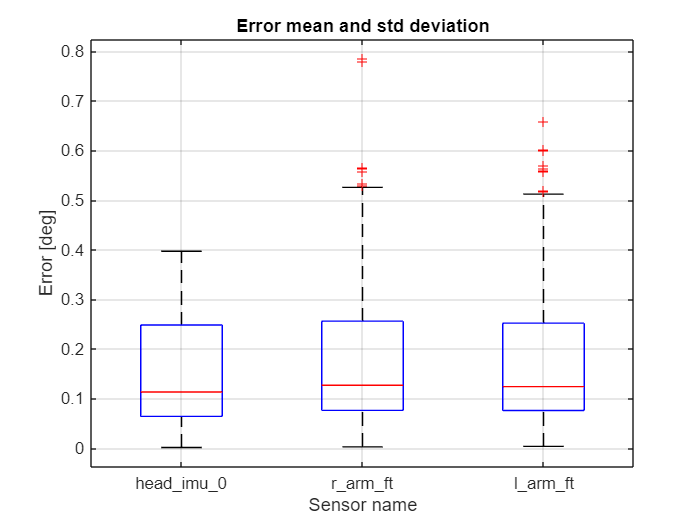

figure
boxplot(error', string(sensorName));
grid on
xlabel("Sensor name")
ylabel("Error [deg]")
title("Error mean and std deviation");

for i = 1:numel(fieldnames(orientations))
    maxError = max(error(i,:));
    fprintf("Testing %s sensor...", string(sensorName(i)));
    fprintf("The max error is %f deg \n", maxError);
    if maxError >= rad2deg(0.1)
        Test_result = compose("\xd83d\xdd34")
    else
        Test_result = compose("\xd83d\xdfe2")
    end
end

Testing head_imu_0 sensor...

The max error is 0.396720 deg 


Test_result = "🟢"

Testing r_arm_ft sensor...

The max error is 0.785443 deg 


Test_result = "🟢"

Testing l_arm_ft sensor...

The max error is 0.658126 deg 


Test_result = "🟢"